%Quatum coursework assignment
%Jack Cornwall - C0037685
%Question 2) a)
clear all

%declaring symbolic variables
syms k L0 L1 T0 T1 G

%declaring probability equations
T0 = G*exp(-2*k*L0)
T1 = G*exp(-2*k*L1)

%stating equation
eqn = (T1/T0 == exp(-k*L0))

%solving for L1 in terms of Lo
solve(eqn, L1)

%b)
clear all
clf

%delarying symbolic variables
syms V0

%physical constants
h = 6.62607015*10^-34 %from https://physics.nist.gov/cgi-bin/cuu/Value?h
h_b = h / (2*pi)
e = 1.602176634*10^-19 %from https://physics.nist.gov/cgi-bin/cuu/Value?e
m = 9.1093837015*10^-31 %from https://physics.nist.gov/cgi-bin/cuu/Value?me

%known values (all in SI units)
E = 2 * e
L = 1 * 10^-9

%declaring equations
k = sqrt(2*m*(V0-E))/h_b;
G = 16*(E/V0)*(1-(E/V0));
T = G*exp(-2*k*L);

%plotting graph
fplot(T)
xlim([3*e 5*e])
ylim([0 1.4*10^-4])

%labelling graph
xlabel("{V_0} [Joules]")
ylabel("Tunelling probability [%]")
title("Tunneling probability plotted against barrier height")
legend("T / {V_0}")

%beautifying curve
box off

%Question 4) d)
clear all
clf

%declaryng symbolic variables
syms k x

%declaring constants
a = 1

a = 1

k0 = 0

k0 = 0

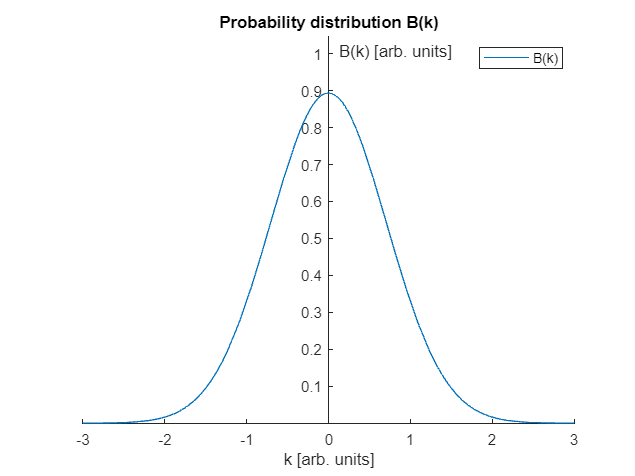


%defining B(k) 
B(k) = ((2*a/pi)^(1/4)) * exp(-a*((k-k0)^2));

%plotting
fplot(B)
xlim([-3 3])
ylim([0 1.05])%this was added in so the 1 would appear on the y axis

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off

%labelling graph
xlabel("k [arb. units]")
ylabel("B(k) [arb. units]")
title("Probability distribution B(k)")
legend("B(k)")


%e)
%performing integral
WP(x) = (1/sqrt(2*pi)) * int(B*exp(1i*k*x),k,-inf,inf)

$$WP(x) = \frac{57821537106012535442281462402195\,\sqrt{\pi }\,{\mathrm{e}}^{-\frac{x^{2}}{4}}}{162259276829213363391578010288128}$$

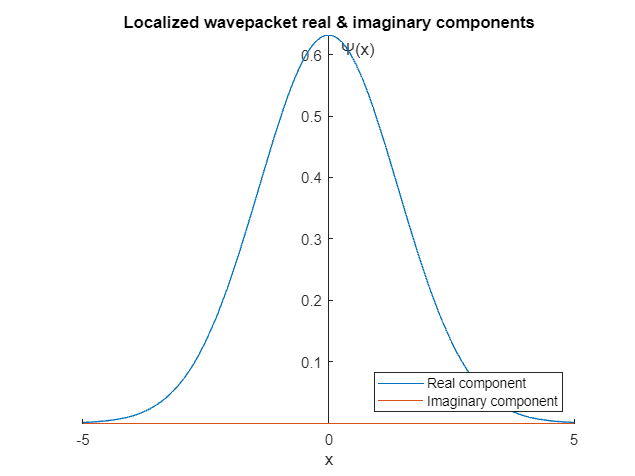


%plotting wavepacket
fplot(real(WP))
hold on
fplot(imag(WP))
hold off
%sometimes MATLAB reports errors with this plot, if it does, I found
%running it multiple times cleared these (I cannot find issues with the
%script)

%beautifying curve
ax = gca;
ax.XAxisLocation = "origin";
ax.YAxisLocation = "origin";
box off

%labelling graph
xlabel("x")
ylabel("{\Psi}(x)")
title("Localized wavepacket real & imaginary components")
legend("Real component","Imaginary component","Location","SouthEast")


%f)
% multiplying wavepacket by complex conjugate & integrating over all space
P = int(WP(x)*conj(WP(x)),x,-inf,inf);

%evaluating probability (P should equal 1)
eval(P)

ans = 1.0000

%question 5) c)
clear all

%physical constants
h = 6.62607015*10^-34; %from https://physics.nist.gov/cgi-bin/cuu/Value?h
h_b = h / (2*pi);

%declaryng symbolic variables
syms k x

%declaring constants
a = 1;
k0 = 3;

%defining B(k) 
B(k) = ((2*a/pi)^(1/4)) * exp(-a*((k-k0)^2));

%performing integral to generate wavepacket
Psy(x) = (1/sqrt(2*pi)) * int(B*exp(1i*k*x),k,-inf,inf);

%performing integral for <Px>
Px = int((conj(Psy(x)) * (-1i*h_b) * diff(Psy(x),x)),x,-inf,inf);
eval(Px)

%d)
%plotting probability distribution B(k)
fplot(B(k))
hold on %plotting on same graph


%plotting real component of wavepacket
fplot(real(Psy(x)))
hold on %plotting on same graph

%plotting imaginary component of wavepacket
fplot(imag(Psy(x)))
hold off %end of plotting

%labelling graph
xlabel("")
ylabel("")
title("Distribution + real & imag components of {\Psi}")
legend("Probability distribution","Real component","Imaginary component","Location","NorthWest")

%question 5) c)
clear all
clf

hold off

%physical constants
h = 6.62607015*10^-34; %from https://physics.nist.gov/cgi-bin/cuu/Value?h
h_b = h / (2*pi);

%declaryng symbolic variables
syms k x

%declaring constants
a = 1;
k0 = 3;

%defining B(k) 
B(k) = ((2*a/pi)^(1/4)) * exp(-a*((k-k0)^2));

%performing integral to generate wavepacket
Psy(x) = (1/sqrt(2*pi)) * int(B*exp(1i*k*x),k,-inf,inf);

%performing integral for <Px>
Px = int((conj(Psy(x)) * (-1i*h_b) * diff(Psy(x),x)),x,-inf,inf);
eval(Px)

yyaxis right %plotting on right yaxis

%d)
%plotting probability distribution B(k)
fplot(B(k))
ylim([0 1.1]) %setting upper limit of right y axis
hold on %plotting on same graph 

%labelling right y-axis
ylabel("B(k)")

yyaxis left %plotting on left y axis

%plotting real component of wavepacket
fplot(real(Psy(x)))
ylim([-0.7 0.7]) %setting limits of left y axis
hold on %plotting on same graph

%plotting imaginary component of wavepacket
fplot(imag(Psy(x)))
hold off %end of plotting

%labelling left y axis
ylabel("{\Psi(x)}")

%labelling graph
xlabel("k / x")
title("Distribution B(k) + real & imag components of {\Psi(x)}")
legend("Real component","Imaginary component","Probability distribution","Location","NorthWest")

%question 6) c)
clear all

%declaring symbolic variables
syms k x p h

%declaring eigenfunction 
u = k*x*exp(p*x^2)

%applying operator to eigenfunction
-1i*h*x*diff(u,x) + 1i*h*diff((u*x),x);

%simplifying answer
simplify(ans)






%question 7) b) c) d) e)
clear all

%initiating P as 0
P=0;
max = 10 %setting maximum n-1 value (starting point changed to 0)

disp("probability terms") %print to output

%for loop outputting probability terms
for n=0:1:max
   
    Pt = .5*(.5^n)
    
    P = P + Pt;
end
disp("summed probability") %print to output

P=0;%resetting P

%for loop outputting summed probability
for n=0:1:max
   
    Pt = .5*(.5^n);
    
    P = P + Pt
    n
end

%Question 8) a)
clear all

%declaring symbolic variables
syms r z a

%volume of a sphere
V = (4/3) * pi * r^3;

%differentiating
dVdr = diff(V,r)

%b)
%declaring u100
u = (((z^3)/(pi*(a^3)))^.5) * exp((-z*r)/a)

%calculating a function for P
P(r,z,a) = u*u*diff(V,r)

%calvulating first order derivative of P
dP(r,z,a) = simplify(diff(P,r))

%calculating second order derivative of P
d2P(r,z,a) = simplify(diff(dP,r))

%making solve calculations simpler
assume(a>0)
assume(z>0)
assume(r>0) %we dont want the turning point when r=0

%extracting max r as a function oof a & z
solve(dP==0,r)


%setting values fo a0 & z
z1 = 1;
z2 = 118;
a0 = 5.29e-11;

%finding turning points
eval(solve(dP(r,z1,a0)==0,r))

%selecting desired r value at turning point
r1 = ans;

%checking we have a maxima
eval(d2P(r1,z1,a0))

%evaluating max/min r values
2/3.78e10
2/2.23e12

%Question 8) a)
clear all

%declaring symbolic variables
syms k p r

%declaring equation to be integrated
eq = k * r^3 * exp(-p*r)

%performing integration
simplify(int(eq,r))
